[sound, fs]=audioread("C:\Users\Amy\Desktop\DSP\Project\test_sentence.wav");
[entrop,te]=pentropy(sound,fs);
t=1/fs*(0:length(sound)-1);
[myent,l,f]=findE(sound,Lp,fs)

entrop = 	1.0e+02 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


myent = 	1.0e+02 *

   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i


l = 5751

f = 	1.0e+03 *

         0    0.0004    0.0008    0.0012    0.0015    0.0019    0.0023    0.0027    0.0031    0.0035    0.0038    0.0042    0.0046    0.0050    0.0054    0.0058    0.0061    0.0065    0.0069    0.0073    0.0077    0.0081    0.0084    0.0088    0.0092    0.0096    0.0100    0.0104    0.0107    0.0111    0.0115    0.0119    0.0123    0.0127    0.0131    0.0134    0.0138    0.0142    0.0146    0.0150    0.0154    0.0157    0.0161    0.0165    0.0169    0.0173    0.0177    0.0180    0.0184    0.0188


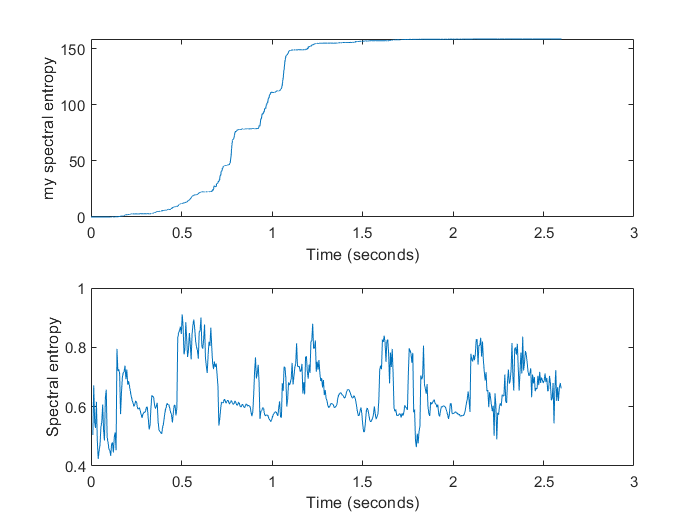


sep=2.6/l;
ender=sep*l;
tent=(0:sep:ender-sep);

%plot entropy

subplot(2,1,1);
plot(tent,myent);
xlabel('Time (seconds)')
ylabel('my spectral entropy')
% plot(t,sound);
% xlabel('Time (seconds)')
% ylabel('original signal')

subplot(2,1,2);
plot(te,entrop);
xlabel('Time (seconds)')
ylabel('Spectral entropy')

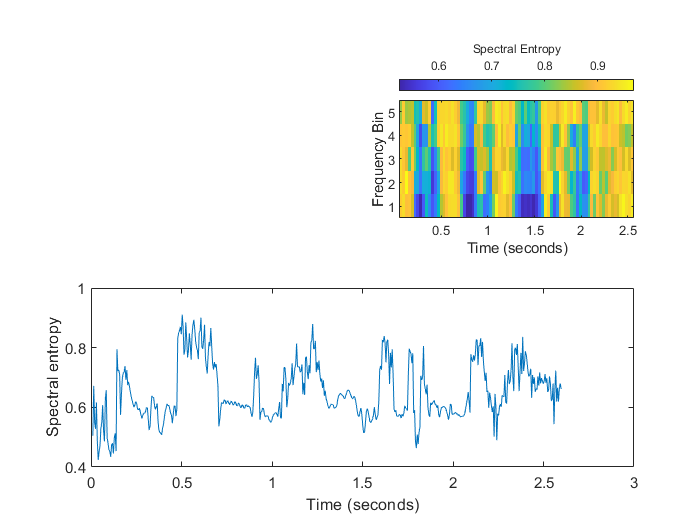



[p,fp,tp] = pspectrum(sound,fs,'FrequencyResolution',20,'spectrogram');

flow = [300 628 1064 1634 2394];
fup = [627 1060 1633 2393 3400];
 
se2 = zeros(length(flow),size(p,2));
for i = 1:length(flow)
    se2(i,:) = pentropy(p,fp,tp,'FrequencyLimits',[flow(i) fup(i)]);
end


subplot(2,2,2);
imagesc(tp,[],flip(se2))    % Flip se2 so its plot corresponds to the ascending frequency bins.
h = colorbar(gca,'NorthOutside');
ylabel(h,'Spectral Entropy')
yticks(1:5)
set(gca,'YTickLabel',num2str((5:-1:1).')) % Label the ticks for the ascending bins.
xlabel('Time (seconds)')
ylabel('Frequency Bin')

function [entrop, len,f]= findE(mysignal, Lp,fs)

fourier = fft(mysignal);
%fourier= abs(fourier);
L=length(fourier);
f=fs*(0:(L/2))/L;
% impulse=impz(Lp);
% fourier=conv(fourier, impulse);
temp=fourier(250:1:6000);

% energy density = fourier transform^2
temp=temp.^2;
c=sum(temp);

%find the probability density function= energy(i)/sum of all energy
pdf=temp./c;
pdf= pdf.*log2(pdf); 
%can multiply by a weighting factor here
entrop=-cumsum(pdf);

%entrop=pentropy(mysignal);
%returns NORMALISED entrop---- entropy/log2(number elements)
%entrop=ifft(pdf);

len= length(entrop);
end

